# Electron in Periodic Potential

## Initialisation

clear
Proj = currentProject;

MASK = @(A, M, val) subsasgn(A, struct("type", "()", "subs", {{M}}), val); %#ok<SUBSASGN> 
VECTOR = @(A, dim) reshape(A, [ones(1, dim-1) numel(A) 1]);

## 1D

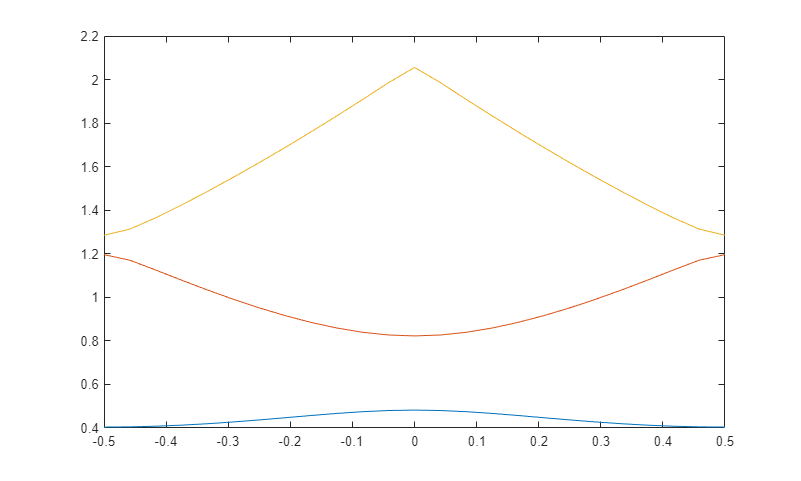

% k = 0;
N = 10;
h = (-N:N).';
Uk = @(h) MASK(-h.^-2, ~h, 0);

Nk1 = 25;
k1 = linspace(-1, 1, Nk1)*.5;
E1 = zeros(Nk1, length(h));
U = .5*Uk(h-h.');
for nk=1:Nk1
	A = diag(.5*(k1(nk)-h).^2, 0) + U;
	[V, D] = eig(A);
	E1(nk, :) = diag(D);
end

Figure;
plot(k1, E1(:, 2:4))

## 2D

N = 10;
UK = @(dh, dk) -MASK(1./(dh.^2+dk.^2), ~dh & ~dk, 0);
UK = @(h, k) reshape(UK(VECTOR(h, 1)-VECTOR(h, 3), VECTOR(k, 2)-VECTOR(k, 4)), length(h)*length(k), []);

Nk2 = 25;
k2 = linspace(-1, 1, Nk2)*.5;
E2 = zeros(Nk2, (2*N+1)^2);
U = .1*UK(-N:N, -N:N);
for nk=1:Nk2
	q2 = (k2(nk) - (-N:N).').^2 + (-N:N).^2;
	A = diag(.5*q2(:)) + U;
	[V, D] = eig(A);
	E2(nk, :) = diag(D);
end

Figure;

ans =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [10 50 1000 600]
       Units: 'pixels'

  Show all properties

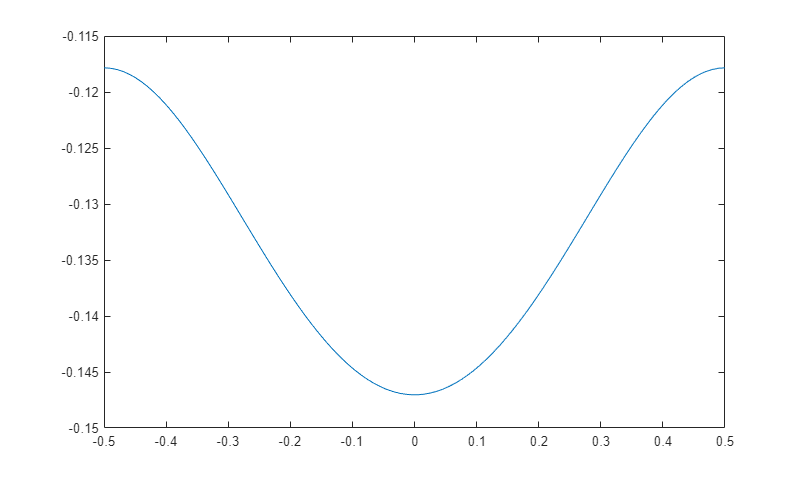

plot(k2, E2(:, 1))

## Functions

function fig = Figure(Arg)
%	Returns handle to figure window, clears figure and sets its size & units.
arguments
	Arg.Fig = gcf;
	Arg.Width = 1000;
	Arg.Height = 600;
	Arg.Units = "Pixels";
end
fig = Arg.Fig;
clf(fig);
fig.Units = Arg.Units;
fig.Position = [10 50 Arg.Width Arg.Height];
colormap(fig, "turbo");
end
